t = 1:1830

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t = t'

t =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


t1 = 1:18347

t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t1 = t1'

t1 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


xdot = Position.speed

xdot =     0.0270
    0.0180
    0.0520
    0.0570
    0.1910
    0.7490
    1.5610
    2.1030
    2.3920
    2.7800


grade = Orientation.Z

grade =    -0.8770
   -0.8797
   -0.8735
   -0.8779
   -0.8799
   -0.8761
   -0.8764
   -0.8798
   -0.8718
   -0.8694


gradeneu = grade(1:10:18300);
grade1 = interp1(grade, t)

grade1 =    -0.8770
   -0.8797
   -0.8735
   -0.8779
   -0.8799
   -0.8761
   -0.8764
   -0.8798
   -0.8718
   -0.8694


%d1 = designfilt('lowpassiir')
d1 = designfilt('lowpassfir')

designfilt('lowpassfir','PassbandFrequency',100,'StopbandFrequency',120,'PassbandRipple',1,'StopbandAttenuation',60,'SampleRate',1830);


d1 =  digitalFilter with properties:

           Coefficients: [5.5659e-04 9.2795e-05 -1.7579e-05 -2.2752e-04 -5.4448e-04 -9.6543e-04 -0.0015 -0.0020 -0.0026 -0.0032 -0.0036 -0.0039 -0.0040 -0.0039 -0.0035 -0.0028 -0.0020 -0.0010 -8.5457e-07 9.6375e-04 0.0018 0.0023 0.0026 0.0025 0.0021 … ]

   Specifications:
      FrequencyResponse: 'lowpass'
        ImpulseResponse: 'fir'
             SampleRate: 1830
    StopbandAttenuation: 60
      PassbandFrequency: 100
         PassbandRipple: 1
      StopbandFrequency: 120
           DesignMethod: 'equiripple'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


d2 = designfilt('lowpassfir')

designfilt('lowpassfir','PassbandFrequency',100,'StopbandFrequency',120,'PassbandRipple',1,'StopbandAttenuation',60,'SampleRate',1830);


d2 =  digitalFilter with properties:

           Coefficients: [5.5659e-04 9.2795e-05 -1.7579e-05 -2.2752e-04 -5.4448e-04 -9.6543e-04 -0.0015 -0.0020 -0.0026 -0.0032 -0.0036 -0.0039 -0.0040 -0.0039 -0.0035 -0.0028 -0.0020 -0.0010 -8.5457e-07 9.6375e-04 0.0018 0.0023 0.0026 0.0025 0.0021 … ]

   Specifications:
      FrequencyResponse: 'lowpass'
        ImpulseResponse: 'fir'
             SampleRate: 1830
    StopbandAttenuation: 60
      PassbandFrequency: 100
         PassbandRipple: 1
      StopbandFrequency: 120
           DesignMethod: 'equiripple'

 Use fvtool to visualize filter
 Use designfilt to edit filter
 Use filter to filter data


%Hz 100 120
x = filtfilt(d1, gradeneu)

x =    -0.7802
   -0.5892
   -0.3781
   -0.1298
    0.1674
    0.5174
    0.9156
    1.3488
    1.7959
    2.2298


y = filtfilt(d2, grade1)

y =    -0.7802
   -0.7773
   -0.7752
   -0.7748
   -0.7766
   -0.7812
   -0.7888
   -0.7995
   -0.8130
   -0.8290


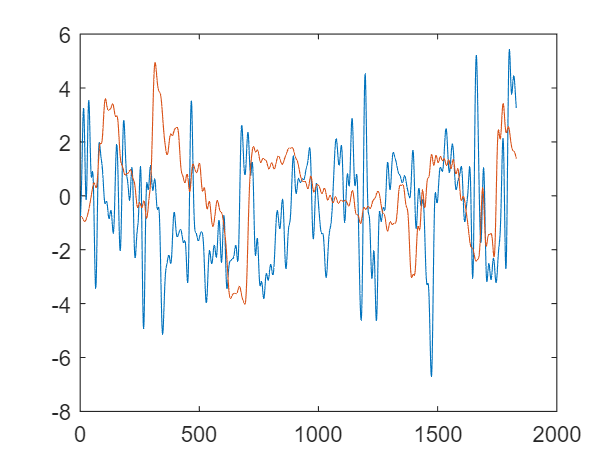

plot(x)
hold on
plot(y)

%plot(gradeneu)
%plot(xdot)




myCycle = [t,xdot];
myGrade = [t1, grade];
%intp1 